% Age structured model
% Set initial conditions
% Runs model to get optimal effort to obtain maximum catch then saves parameters
% Fikri Sjahruddin
% 7th of April 2022
% Fisheries Spatial Explicit Model

cd ('C:\Users\uqffirma\MATLAB\Projects\FSM\')

%% run and generate initial parameters
fish_list = ["parrot fish" "snapper" "coral trout" "rabbit fish"]; %ordered list species in spparams

num_sp = numel(fish_list);


run sp_parameters.m ;%num_sp is number of all species in spparams

flenm = char('Params_sp');  %set file name to save parameters generated on this code

%% Check length-weight relationship of each species
% Select species which will be plotted

species = "snapper" % Select species of interest

species = "snapper"


for i = 1: numel(fish_list)
        if species == fish_list(i)
        index_sp = i;
    else
    end
end
[spparams] = select_spparams (spparams, index_sp)

spparams = struct with fields:
          nages: 12
              q: 1
              M: 0.3400
         matind: [1 1 1 1 1 1 1 1 1 1 1 1]
        weights: [25.2773 95.1629 185.3878 273.4617 348.5056 407.7593 452.4393 485.1612 508.6739 525.3571 537.0942 545.3041]
     weightsmat: [12×433 double]
       fecparam: 1
             CR: 4
           Rmax: 1
       afishind: [12×433 double]
         RelVal: 2
          alpha: 0.0747
           beta: 0.0561
          Lzero: 53.5193
          mrate: 0.0100
          omega: 0
    minbio_prof: 0.0500
        nmonths: 12
             dT: 0.0833


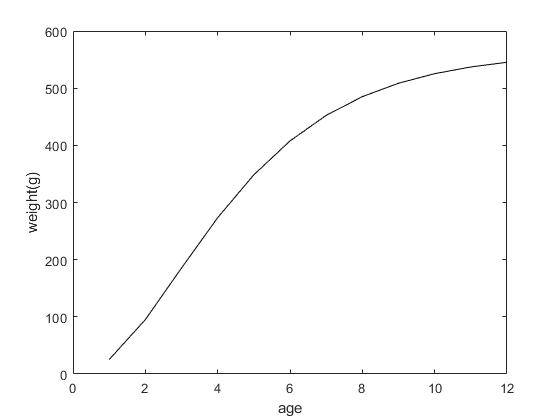

%Create plot of age vs weight
figure
plot(1:spparams.nages, spparams.weights, 'k')
xlabel('age'); ylabel('weight(g)')

%% Initial parameters
Ninit = spparams.Rmax; % intial abundance based on pre-set up maximum recruitment

% MPA status of each individual reefs
tmax = 100; 
reefs_status = zeros(tmax, no_reefs);

% Year of MPA being established 
startmpa = 50;


% Set fishing pressure reduction rate or fishing pressure remains within FMPA 
% This fishing pressure reduction only happens in FMPA
Frem = 0.5; % this means that fishing effort within FMPA remains 50% compared to previous fishing effort before MPA was established

%% Set fishing mortality assuming fishing does not occur to calculate virgin biomass
umat = arrayfun(@(index_sp) createumat(index_sp, spparams.afishind,0), ...              % 0 is set to represent fishing does not exist
    index_sp, 'UniformOutput',false);% fishing mortality equals to zero (unfished)      
xres =  timeloopfunc(no_reefs, reefs_status, reefs_conn, reefs_std, umat, index_sp, Ninit,spparams, tmax, startmpa,Frem);
b_unfished = xres.Biomass(tmax, 1) %unfished biomass when fishing does not occur

b_unfished = 0.6955

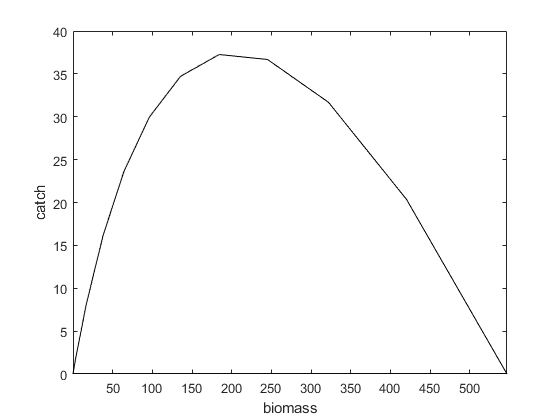

%% Find Fmsy (Eopt) under no MPA impelentation
nvals = 20; %setting number to generate fishing effort
uvals = linspace(0,0.8,nvals); %fishing efforts
catchvals = nan(nvals,1); %catch resulted based on fishing efforts applied
biovals = nan(nvals,1); %biomass resulted based on fishing efforts applied

for ivals = 1:nvals   %number of diffrerent fishing efforts
umat = arrayfun(@(index_sp) createumat(index_sp, spparams.afishind, uvals(ivals)),index_sp, 'UniformOutput',false);
xres =  timeloopfunc(no_reefs, reefs_status, reefs_conn, reefs_std, umat, index_sp, Ninit,spparams, tmax, startmpa,Frem);
 %only for one species
 catchvals(ivals)= sum(xres.Catches(tmax,:));
 biovals(ivals) = sum(xres.Biomass(tmax,:));
end

figure
	plot(biovals, catchvals, 'k'); xlabel ('biomass'); ylabel ('catch')
    xlim([min(biovals) max(biovals)])
    %ylim([round(min(catchvals)) ceil(max(catchvals))])
	yline(0,'k')

%% Find optimum effort to generate max catch using fminsearch and fmincon
%%%% Run models to find Fmsy
%%% Find optimal effort 


nvals = 1; %nvals = 1 because optimisation is being focused on values on each simulations

% x = Etot, optimum effort to generate maximum yield
fun = @(x) -getvalsMP_sp(nvals, no_reefs, reefs_status,reefs_conn, reefs_std,x, index_sp,spparams, Ninit, tmax, startmpa,Frem); %functions used in the optimisation. It is used because it generates output total catch for each species all over the zones 
x0 = 0; %simulation starts 
options = optimset('Display','iter');
[Eopt Copt] = fminsearch(fun,x0, options)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1               -0         
     1            2        -0.154918         initial simplex
     2            4        -0.463384         expand
     3            6         -1.07486         expand
     4            8         -2.27624         expand
     5           10         -4.59443         expand
     6           12         -8.90628         expand
     7           14          -16.334         expand
     8           16         -27.1178         expand
     9           18         -36.7616         expand
    10           20         -37.4289         contract outside
    11           22         -37.4289         contract inside
    12           24         -37.4629         contract inside
    13           26         -37.4629         contract inside
    14           28          -37.466         contract inside
    15           30          -37.466         contract inside
    16           32          -37.466         contract

Eopt = 0.1536

Copt = -37.4661

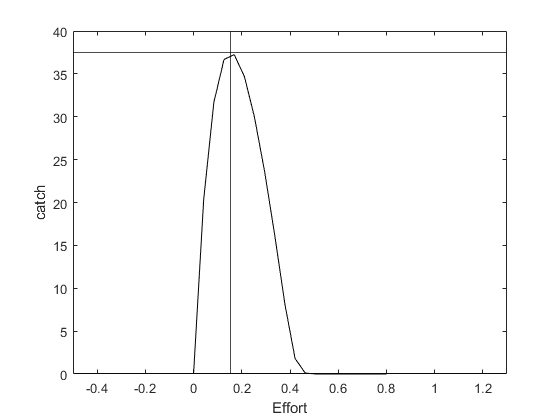

figure
	plot(uvals, catchvals, 'k'); xlabel ('Effort'); ylabel ('catch');
    xlim([min(uvals)-0.5 max(uvals)+0.5]);
	xline(Eopt,'k');
    yline(-Copt,'k');
	yline(0,'k');

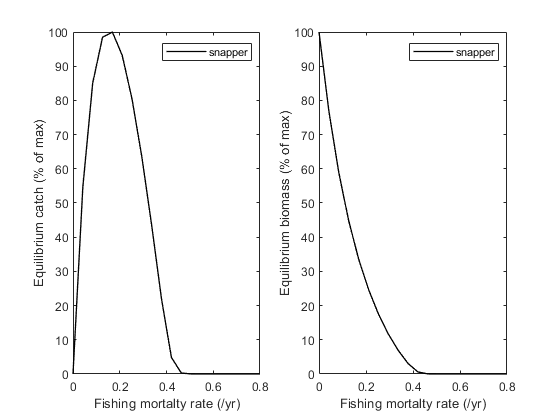


%% Effort plot for paper
figure

lstyle = {'-' };
lcolor = [0 0 0];

maxcatch = max(catchvals);
subplot(1,2,1);
plot(uvals,100*catchvals/maxcatch, lstyle{1,1}, 'Color', lcolor,'LineWidth',1, 'MarkerFaceColor','k', 'MarkerSize',4, 'DisplayName',fish_list(index_sp));
xlabel('Fishing mortalty rate (/yr)'); ylabel('Equilibrium catch (% of max)');
legend(fish_list(index_sp));    

subplot(1,2,2)
maxbio = max(biovals);
plot(uvals,100*biovals/maxbio, lstyle{1,1}, 'Color', lcolor,'LineWidth',1, 'MarkerFaceColor','k', 'MarkerSize',4, 'DisplayName',fish_list(index_sp));
xlabel('Fishing mortalty rate (/yr)'); ylabel('Equilibrium biomass (% of max)');
legend(fish_list(index_sp));

%% Plot N1, Biomass, and Catch over time for two scenarios
% Scenario 0, FP = 1 = Fmsy, no MPA, no reserve
% Scenario 1, FP = 1 = Fmsy, reserve = 30%, FMPA = 20%

%Fishing pressure st up
FPmult = [1 1.5 2.0];
Btot = Eopt * FPmult(3); %Fishery condition is set as overfished
umat = arrayfun(@(index_sp) createumat(index_sp, spparams.afishind,Btot), ...
    index_sp, 'UniformOutput',false); %This makes u or fishing efforts are the same for all species


%run scenario over time

%Scenario_0
reefs_status_0 = reefs_status.*0;
Frem = 0; % sets for no MPA contion, there is no way to have fishing pressure reduction
xres_0 = timeloopfunc(no_reefs, reefs_status_0, reefs_conn, reefs_std, umat, index_sp, Ninit,spparams, tmax, startmpa,Frem); %Scenario 0 - No MPA condition
 
%Scenario_1
Frem = 0.5; % sets for FMPA reefs
reefs_status_1 = reefs_status_0;
reefs_status_1(50:100,1:50) = 1;
reefs_status_1(50:100,101:150) = 0.5;

xres_1 = timeloopfunc(no_reefs, reefs_status_1, reefs_conn, reefs_std, umat, index_sp, Ninit,spparams, tmax, startmpa,Frem); %Scenario 1
 
Scenarios = {xres_0 xres_1};

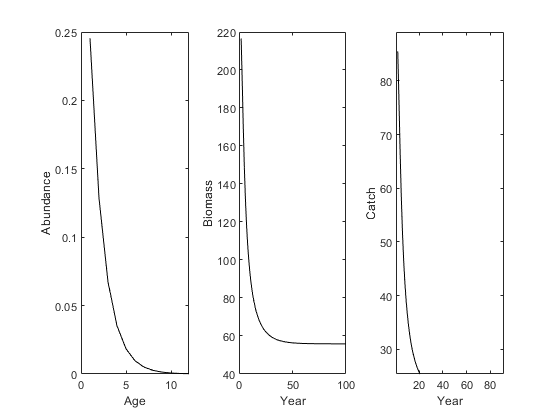

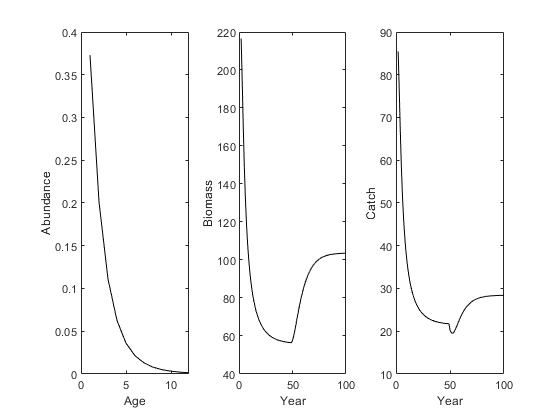

% Create N1 (abundance at a time(year), catch, and biomass panel plot
for p = 1:numel(Scenarios)

figure

xres = Scenarios{1,p};

    subplot(1,3,1)
	plot(sum(xres.N1{1,1}(:,:),2), 'k');
    xlabel ('Age'); ylabel ('Abundance');
   
	subplot(1,3,2)
	plot(1:tmax, sum(xres.Biomass(:,:),2), 'k')
    ylim = [0 max(sum(xres.Biomass(:,:),2))];
    xlabel ('Year'); ylabel ('Biomass');
	  
    subplot(1,3,3)
    plot(1:tmax, sum(xres.Catches(:,:),2), 'k')
    ylim = [0 max(sum(xres.Catches(:,:),2))];
    xlabel ('Year'); ylabel ('Catch');
end

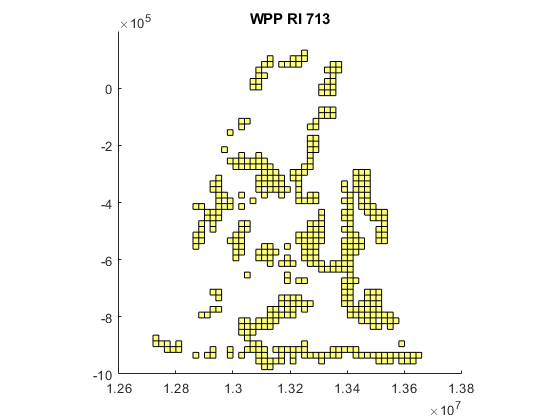

figure
PU = shaperead('C:\Users\uqffirma\MATLAB\Projects\FSM\pu\wpp_713_pu_20k.shp');
mapshow(PU)
title('WPP RI 713');

connectivity = reefs_conn;
imagesc(1:433,1:433,connectivity)


%% Save parameters

output =struct();
output.spparams = spparams;
output.Copt = Copt;
output.Eopt = Eopt;
output.FPmult = FPmult;
output.nmonths = spparams.nmonths;
output.dT = spparams.dT;
output.Ninit = Ninit;

save( flenm, 'output') %save all object as output object    